load awesomeMap.mat
map = binaryOccupancyMap(grid);

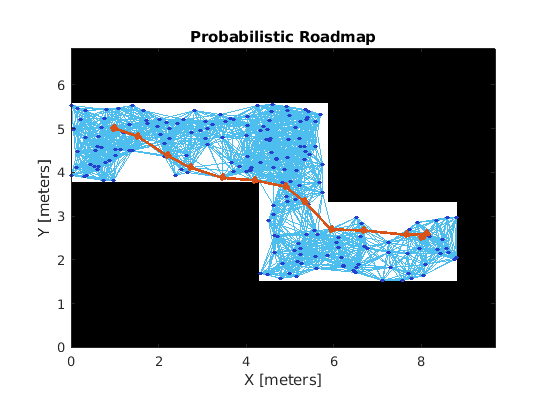

prmComplex = mobileRobotPRM(map,200);

startLocation = [1 5];
endLocation = [8 2.5];

prmComplex.ConnectionDistance = 1;
path = findpath(prmComplex, startLocation, endLocation);
a = repelem(startLocation,length(path),1);
path = path - a;
show(prmComplex)

rosshutdown

Shutting down global node /matlab_global_node_05794 with NodeURI http://10.42.0.28:37119/


init_turtlebot_connection("10.42.0.1", "10.42.0.28");

Initializing global node /matlab_global_node_65334 with NodeURI http://10.42.0.28:37537/


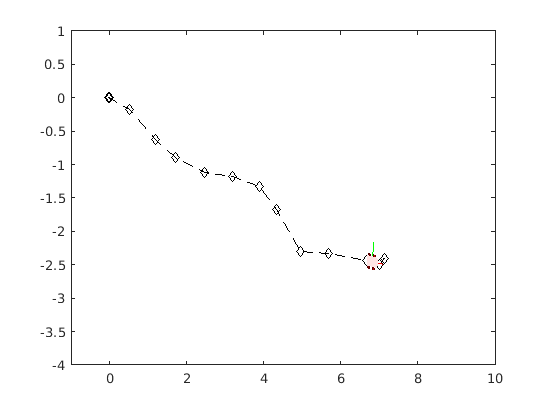


simplePath = [0 0;1 0 ; 2 0; 3 0; 4 0];
myPurePursuit(path)